# Problema 1 - Tp7

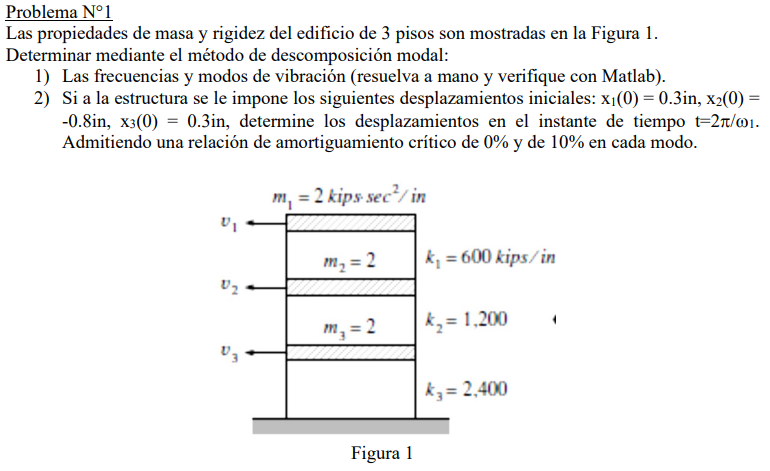

## Respuestas para comparar

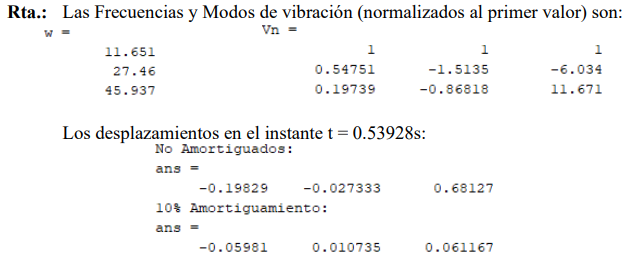

## Obtención de matrices M y K

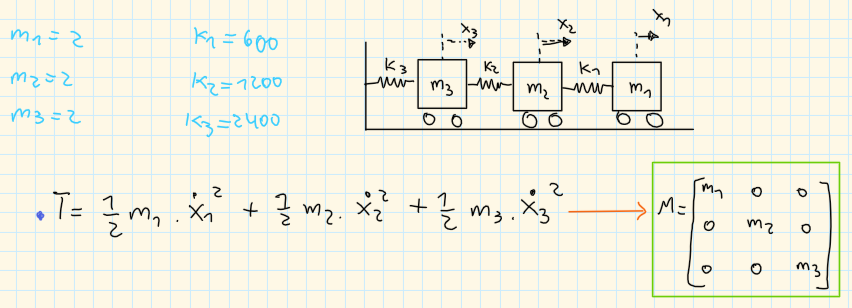

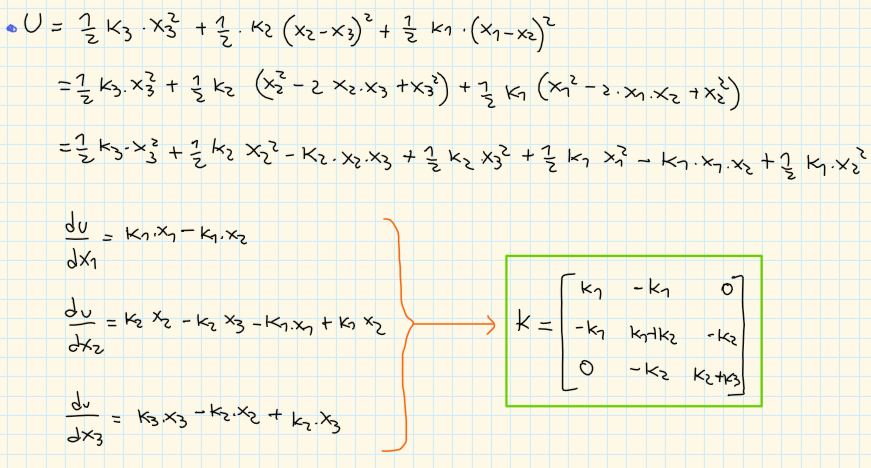

## Cálculo de autovalores y autovectores

clc; clear;

%%--------------DATOS DEL SISTEMA------------------------------------

%Masas
m1=2;
m2=2;
m3=2;

M = diag([m1,m2,m3]);

%Rigidez
k1=600;
k2=1200;
k3=2400;

K = [k1 -k1 0;
    -k1 k1+k2 -k2;
    0 -k2 k2+k3];

%Tiempo para graficar
tf=2;
dt=0.000001;
t=0:dt:tf;

%%--------------- CONDICIONES INICIALES -------------------------------

x0 = [0.3; -0.8; 0.3]; %Desplazamientos iniciales
dx0 = [0; 0; 0] ; %Velocidades iniciales

%%--------------AUTOVALORES Y AUTOVECTORES------------------------------------

[V,lambda] = eig(K,M);  %V es la matriz modal, donde cada columna es un autovector
%la matriz lambda es una matriz que contiene a los autovalores en su diagonal.

disp("Las frecuencias angulares en [rad/s] son:")

Las frecuencias angulares en [rad/s] son:


w = diag(sqrt(lambda))  %[rad/s]

w =    11.6511
   27.4598
   45.9370


%Estas son las frecuencias naturales de cada modo de vibración

%disp("Las frecuancias en [Hz]:")
f = w/(2*pi); %[Hz]

%disp("Autovectores normalizados por el programa:")
V;

disp("Los autovectores normalizados respecto del primer elemento son:")

Los autovectores normalizados respecto del primer elemento son:


V_norm = V ./ V(1,:)

V_norm =     1.0000    1.0000    1.0000
    0.5475   -1.5135   -6.0340
    0.1974   -0.8682   11.6708


## RELACION DE AMORTIGUAMIENTO NULA

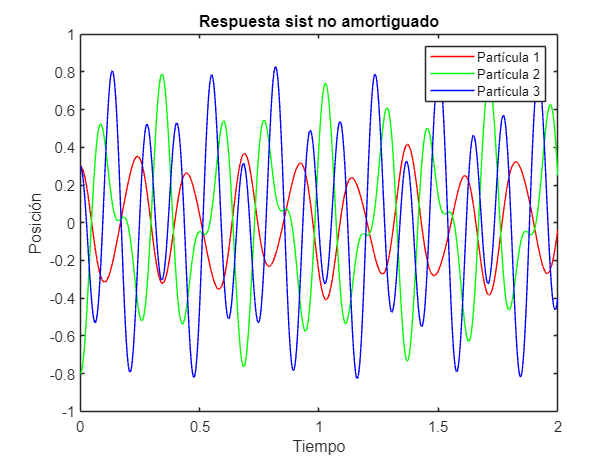

zitta = 0;

%%--------------METODO DE DESCOMPOSICIÓN MODAL------------------------------------

%disp("Para calcular Mmodal y Kmodal se usa el V normalizado por el programa. Esto hace que Mmodal sea una matriz identidad y que Kmodal contenga en diagonal a w^2:\n")
Mmodal = round(V' * M * V); %Matriz de masas modales
%Podemos ver que Mmodal es muy proxima a una matriz identidad.
Kmodal = round(V' * K * V);

%Paso de coordenadas geométricas a coordenadas modales
Y0 = V' * M * x0;
dY0 = V' * M * dx0;

%%--------------RESOLUCIÓN EDO------------------------------------

%Ahora tengo un sistema del tipo Mmodal*y''+Kmodal*y=0 Como Mmodal y Kmodal
%son diagonales, es como si tuviera varias ecuaciones diferenciales
%simples.

%Para sistemas sin amortiguación y en vibraciones libres la fórmula es:
%x(t) = x0*cos(wn*t) + dx0/wn * sin(wn*t)

Y1 = zeros(length(w),length(t));

for i = 1:length(w)
    Y1(i,:) = Y0(i).*cos(w(i)*t) + dY0(i)/w(i).*sin(w(i)*t);
end

%Ahora paso de coordenadas modales a geométricas
X1 = V * Y1;

% Graficar las posiciones de las partículas
figure(1)
plot(t, X1(1,:), 'r', t, X1(2,:), 'g', t, X1(3,:), 'b');
xlabel('Tiempo');
ylabel('Posición');
legend('Partícula 1', 'Partícula 2', 'Partícula 3');
title('Respuesta sist no amortiguado');

## RELACION DE AMORTIGUAMIENTO DEL 10% PARA TODOS LOS MODOS

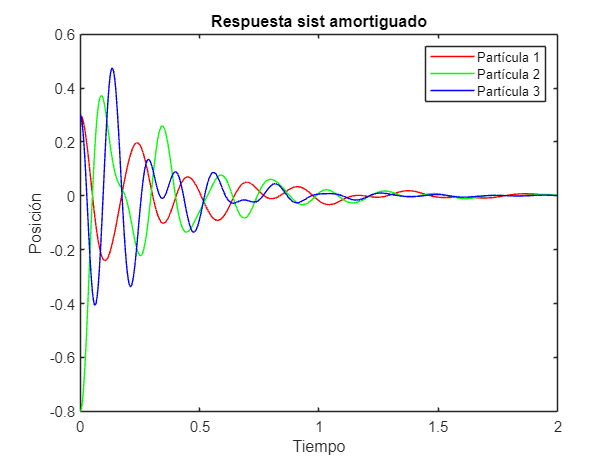

zitta = [0.1; 0.1; 0.1];
Cmodal = 2*zitta.*w.*eye(size(M)); %Cmodal
%La ecuación diferencial a resolver es la siguiente:
%Mmodal*y''(t) + Cmodal*y'(t) + Kmodal*y(t) = 0

%%--------------RESOLUCIÓN EDO------------------------------------

%Ahora tengo un sistema del tipo Mmodal*y''+Kmodal*y=0 Como Mmodal y Kmodal
%son diagonales, es como si tuviera varias ecuaciones diferenciales
%simples.

%Para sistemas amortiguados, la solución es::
%

wd = w.*sqrt(1-zitta.^2); %frecuencia natural del sistema amortiguado
e=exp(1);

Y2 = zeros(length(w),length(t));

for i = 1:length(w)
    
    %Primer término
    Y2(i,:) = e.^(-zitta(i)*w(i)*t).*( cos(wd(i)*t) + zitta(i)/sqrt(1-zitta(i)^2) * sin(wd(i)*t)).*Y0(i);
    
    %Segundo término
    Y2(i,:) = Y2(i,:)+ dY0(i) * (1/wd(i)*e.^(-zitta(i)*w(i)*t).*sin(wd(i)*t));
    
    %El tercer término no afecta porque es sólo si hay cargas externas
    %aplicadas
end

%Ahora paso de coordenadas modales a geométricas
X2 = V * Y2;

% Graficar las posiciones de las partículas
figure(2)
plot(t, X2(1,:), 'r', t, X2(2,:), 'g', t, X2(3,:), 'b');
xlabel('Tiempo');
ylabel('Posición');
legend('Partícula 1', 'Partícula 2', 'Partícula 3');
title('Respuesta sist amortiguado');


%%--------------DESPLAZAMIENTOS PARA t=2*Pi/w1------------------------------------

t_evaluar = 2*pi/w(1);

disp(['Para t=',num2str(t_evaluar),' s']);

Para t=0.53928 s



disp("Para caso sin amortiguación:")

Para caso sin amortiguación:


x1 = interp1(t,X1(1,:),t_evaluar)

x1 = -0.2046

x2 = interp1(t,X1(2,:),t_evaluar)

x2 = -0.0219

x3 = interp1(t,X1(3,:),t_evaluar)

x3 = 0.6982


disp("Para caso con amortiguación:")

Para caso con amortiguación:


x1 = interp1(t,X2(1,:),t_evaluar)

x1 = -0.0615

x2 = interp1(t,X2(2,:),t_evaluar)

x2 = 0.0127

x3 = interp1(t,X2(3,:),t_evaluar)

x3 = 0.0639